clc,clear,close all
load result.mat
load slanCM_Data.mat

[sequences1, labels1, outputs1, targets1, error1] = dataLoader(train1, 15);

RMSE = single
0.0121

[sequences2, labels2, outputs2, targets2, error2] = dataLoader(train2, 15);

RMSE = single
0.0199

[sequences3, labels3, outputs3, targets3, error3] = dataLoader(train3, 15);

RMSE = single
0.0188

[sequences4, labels4, outputs4, targets4, error4] = dataLoader(train4, 15);

RMSE = single
0.0167



function [sequences, labels, outputs, targets,errors] = dataLoader(data, window_size)
    windows = window_size;
    outputs = data(1,:);
    targets = data(2,:);
    errors = outputs-targets;
    labels = zeros([length(outputs)-windows, 1]);
    for j = windows+1:length(outputs)
        sequences{j-windows} = outputs(j-windows:j); 
        labels(j-windows) = targets(j);
    end
    RMSE=sqrt(mean(errors.^2))
end





## model define

train = [sequences1,sequences2,sequences3,sequences4];
targets = [labels1;labels2;labels3;labels4];

Output_size = 1;
Input_size = 1;
numHiddenUnits = 256; 
layers = [ ...
    sequenceInputLayer(Input_size)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(9)
    reluLayer
    fullyConnectedLayer(Output_size)
    regressionLayer];


options = trainingOptions('adam', ...
    'MaxEpochs',500, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',100, ...
    'LearnRateDropFactor',0.2, ...
    'GradientThreshold',1, ...
    'Verbose',0);

net = trainNetwork(train,targets,layers,options);



function [pred,Error] = RMSE(net,sequences,labels,errors)
    pred = predict(net, sequences);
    Error = pred-labels;
    RMSE_OG = sqrt(mean((errors).^2))
    RMSE=sqrt(mean((Error).^2))
    MAE=mean(abs(Error))
end
disp('set 1')

set 1


[pred1,Error1] = RMSE(net,sequences1, labels1, error1);

RMSE_OG = single
0.0121

RMSE = single
0.0176

MAE = single
0.0149

disp('set 2')

set 2


[pred2,Error2] = RMSE(net,sequences2, labels2, error2);

RMSE_OG = single
0.0199

RMSE = single
0.0179

MAE = single
0.0132

disp('set 3')

set 3


[pred3,Error3] = RMSE(net,sequences3, labels3, error3);

RMSE_OG = single
0.0188

RMSE = single
0.0155

MAE = single
0.0139

disp('set 4')

set 4


[pred4,Error4] = RMSE(net,sequences4, labels4, error4);

RMSE_OG = single
0.0167

RMSE = single
0.0173

MAE = single
0.0128

colorMap = 'gist_heat';
cmap=slanCM(colorMap,170) ;

@author : slandarer


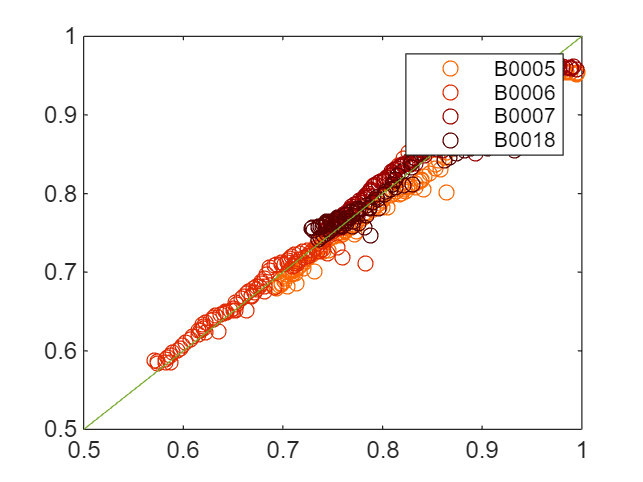


figure(1)
plot(labels1,pred1,'o',Color=cmap(120,:))
hold on
plot(labels2,pred2,'o',Color=cmap(100,:))
hold on
plot(labels3,pred3,'o',Color=cmap(70,:))
hold on
plot(labels4,pred4,'o',Color=cmap(40,:))
hold off
legend('B0005','B0006','B0007','B0018')
line([0.5,1],[0.5,1],'HandleVisibility','off')

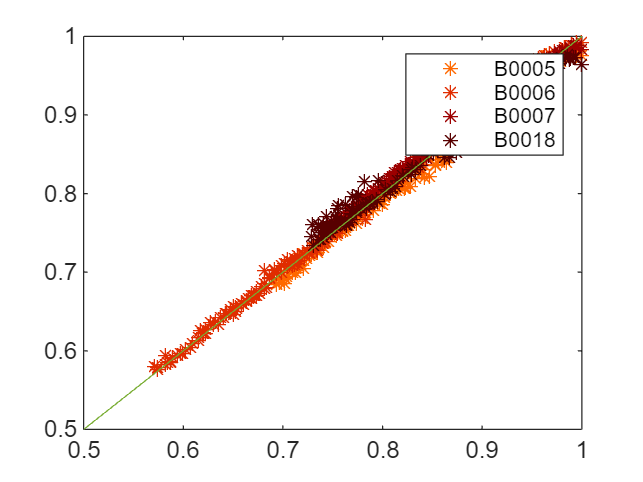


figure(2)
plot(targets1,(3*outputs1+targets1)/4,'*',Color=cmap(120,:))
hold on
plot(targets2,(outputs2+targets2)/2,'*',Color=cmap(100,:))
hold on
plot(targets3,(outputs3+targets3)/2,'*',Color=cmap(70,:))
hold on
plot(targets4,(3*outputs4+targets4)/4,'*',Color=cmap(40,:))
hold off
line([0.5,1],[0.5,1])
legend('B0005','B0006','B0007','B0018')


figure(3)
idx= 5

idx = 5

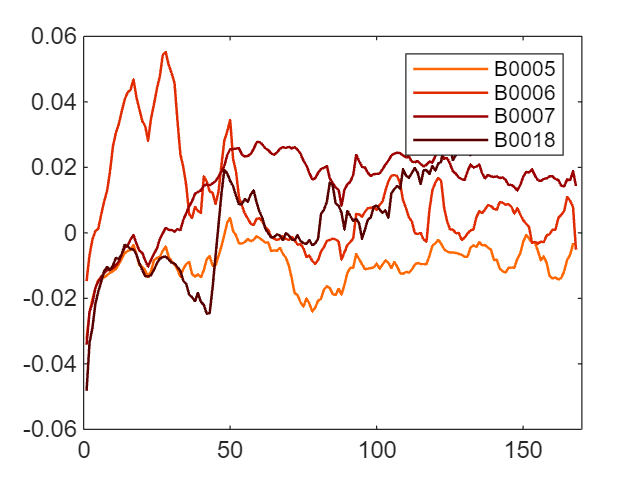

plot(smooth(error1,idx),Color=cmap(120,:),LineWidth=1)
hold on
plot(smooth(error2,idx),Color=cmap(100,:),LineWidth=1)
hold on
plot(smooth(error3,idx),Color=cmap(70,:),LineWidth=1)
hold on
plot(smooth(error4,idx),Color=cmap(40,:),LineWidth=1)
hold off
xlim([0 170])
legend('B0005','B0006','B0007','B0018')


figure(4)
idx = 5

idx = 5

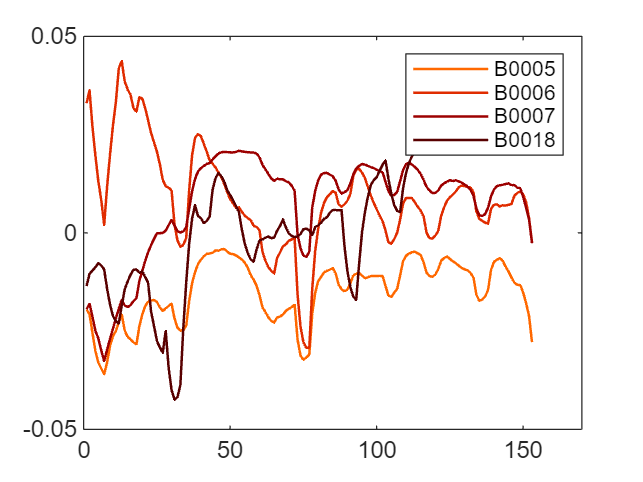

plot(smooth(Error1,idx),Color=cmap(120,:),LineWidth=1)
hold on
plot(smooth(Error2,idx),Color=cmap(100,:),LineWidth=1)
hold on
plot(smooth(Error3,idx),Color=cmap(70,:),LineWidth=1)
hold on
plot(smooth(Error4,idx),Color=cmap(40,:),LineWidth=1)
hold off
xlim([0 170])
legend('B0005','B0006','B0007','B0018')

colorMap = 'tempo';
cmap=slanCM(colorMap,170) ;

@author : slandarer



imageSize_cm = [20 5];
margins_cm = [0 0];
set(gcf, 'PaperPosition', [margins_cm imageSize_cm]);
%set(gcf, 'OuterPosition',[0 0 20 10])
set(gcf,'PaperSize',[20.05 5])
t=tiledlayout(1,4,"TileSpacing","tight", ...
    "Padding","tight");


ax1 = nexttile

ax1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.0300 0.0352 0.2385 0.9497]
            Units: 'normalized'

  Show all properties


plot(labels1,pred1,'o',Color=cmap(120,:))
hold on
plot(labels2,pred2,'o',Color=cmap(100,:))
hold on
plot(labels3,pred3,'o',Color=cmap(70,:))
hold on
plot(labels4,pred4,'o',Color=cmap(40,:))
hold off
legend('B0005','B0006','B0007','B0018',Location='best',FontSize = 6)
line([0.5,1],[0.5,1],'HandleVisibility','off',Color = 'k',LineStyle = '--')
xlim([0.7 1])
xlabel('Real')
ylabel('Estimation')

title('Single cycle - results')

ax2 = nexttile

ax2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.3090 0.0670 0.2068 0.8943]
            Units: 'normalized'

  Show all properties


idx = 2

idx = 2

plot(smooth(Error1,idx),Color=cmap(120,:),LineWidth=1)
hold on
plot(smooth(Error2,idx),Color=cmap(100,:),LineWidth=1)
hold on
plot(smooth(Error3,idx),Color=cmap(70,:),LineWidth=1)
hold on
plot(smooth(Error4,idx),Color=cmap(40,:),LineWidth=1)
hold off
xlim([0 170])
ylim([-0.04 0.07])
legend('B0005','B0006','B0007','B0018',Location='best',FontSize = 4)
title('Single cycle - errors')
xlabel('Cycles number')
ylabel('Error')

ax3 = nexttile

ax3 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5726 0.0670 0.1746 0.8943]
            Units: 'normalized'

  Show all properties


plot(targets1,(3*outputs1+targets1)/4,'*',Color=cmap(120,:))
hold on
plot(targets2,(outputs2+targets2)/2,'*',Color=cmap(100,:))
hold on
plot(targets3,(outputs3+targets3)/2,'*',Color=cmap(70,:))
hold on
plot(targets4,(3*outputs4+targets4)/4,'*',Color=cmap(40,:))
hold off
line([0.5,1],[0.5,1],'HandleVisibility','off',Color = 'k',LineStyle = '--')
legend('B0005','B0006','B0007','B0018',Location='best',FontSize = 6)
xlim([0.7 1])
title('Multi cycle - results')
xlabel('Real')
ylabel('Estimation')

ac4 = nexttile

ac4 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.8214 0.0670 0.1733 0.8943]
            Units: 'normalized'

  Show all properties


idx= 7

idx = 7

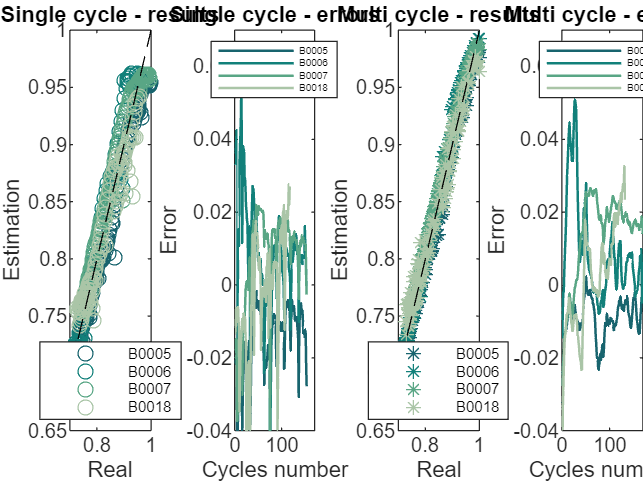

plot(smooth(error1,idx),Color=cmap(120,:),LineWidth=1)
hold on
plot(smooth(error2,idx),Color=cmap(100,:),LineWidth=1)
hold on
plot(smooth(error3,idx),Color=cmap(70,:),LineWidth=1)
hold on
plot(smooth(error4,idx),Color=cmap(40,:),LineWidth=1)
hold off
xlim([0 170])
ylim([-0.04 0.07])
legend('B0005','B0006','B0007','B0018',Location='best',FontSize = 4)
title('Multi cycle - errors')
xlabel('Cycles number')
ylabel('Error')

print('FG_IC', '-dpdf', '-r1200')